clear
load FlightData\Standard_LinY.mat
SoftKite_TL

## Estimation of Efficiencty

C_L = Cl_sim;
C_D = Cd_sim; 
r_l = vecnorm(pos')'; % equivalent to states.signals.values(:,5)
beta = alpha.signals.values - alpha_0;
% alternative and equivalent computation (from definition)
% We = W - posDot;
% beta_alt = pi/2 - acos(dot(We, pos, 2)./(vecnorm(We')'.*vecnorm(pos')'));
C_Deq = C_D.*(1 + (n_line*r_l*parameters.d_l*parameters.Cd_l.*cos(beta))./(4*parameters.A*C_D));


Seems correct, C_Deq is higher bc there is cable drag involved.

The introduction of beta gives minimal difference, the difference is 2 orders of magnitude less than the absolute value 

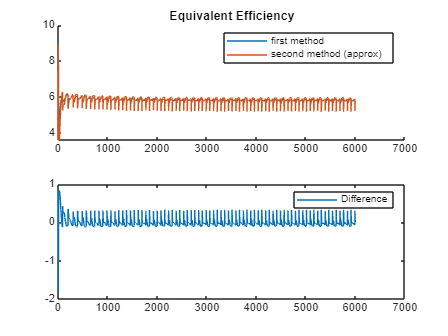

E_eq_1 = C_L./C_Deq;
% The next methods seems to be used more to recover beta than compute E_eq
E_eq_2 = cos(beta)./sin(beta); % Equivalent to 1./tan(beta)
figure, 
subplot(2,1,1), hold on;
plot(E_eq_1), plot(E_eq_2)
title('Equivalent Efficiency')
legend('first method','second method (approx)'), hold off
subplot(2,1,2)
plot(E_eq_1-E_eq_2)
legend('Difference')

They match up pretty well, we can decide to pick any of the two to compute efficiency, maybe first method is less prone to incorrect assumptions

## Computation of W_er_norm

E_eq = E_eq_1;

First approach 

C = 0.5*parameters.rho*parameters.A*C_L.*E_eq.^2.*(1+1./E_eq.^2).^(3/2);
W_er_norm_1 = sqrt(F_T_norm./C);

Second approach 

% for the norm of the kite speed we can use the one from simulation (Vkite) or vecnorm(posDot')', they
% are the same 
W_er_norm_2 = vecnorm(posDot')'./E_eq;

Comparison

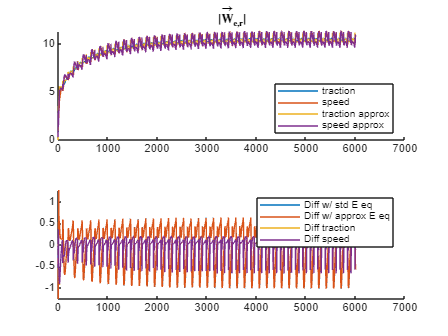

figure

% case with the other computation of efficiency
E_eq = E_eq_2;
C = 0.5*parameters.rho*parameters.A*C_L.*E_eq.^2.*(1+1./E_eq.^2).^(3/2);
W_er_norm_3 = sqrt(F_T_norm./C);
W_er_norm_4 = vecnorm(posDot')'./E_eq;
subplot(2,1,1), hold on
plot(W_er_norm_1), plot(W_er_norm_2)
plot(W_er_norm_3), plot(W_er_norm_4)
title('$\mathbf{|\vec{W}_{e,r}|}$', 'Interpreter','latex')
legend('traction', 'speed', 'traction approx', 'speed approx', 'Location','southeast'), hold off
subplot(2,1,2), hold on
plot(W_er_norm_1 - W_er_norm_2)
plot(W_er_norm_3 - W_er_norm_4)
plot(W_er_norm_1 - W_er_norm_3)
plot(W_er_norm_2 - W_er_norm_4)
legend('Diff w/ std E eq','Diff w/ approx E eq', 'Diff traction', 'Diff speed' ), hold off

The computation of W_e,r with the unapproximaed method of computation of E_eq produces a lot less spikes, as it can be deduced from the plots of E_eq_1 and E_eq_2 

Considering the same Equivalent aerodynamic efficiency, the 2 methods of computation of W_e,r (traction and speed) produce very different results; in particular, the speed approach more spikes, and in general has a more erratic behivour

## Absolute Wind Recovery

W_er_norm = W_er_norm_1; % Select which 
L_dot = statesdot.signals.values(:,5); % unwinding/winding speed
l = pos./(vecnorm(pos')'); % kite position versor

The first approach can be to take 3 measurement at the time, assuming that the wind doesn't change during the measurement and solve system of 3 eq in 3 unknowns

tol = 1e-15;
maxIter = 20;
blockSize = 5;
initStep = 2;
maxStep = 6001; % Shouldn't exceed size(l)
N_filter = 100; % Steps to skip in the comparison (100 steps = 1 sec)
noZ = 1;        % Remove the computation of Wz (1 = yes, 0 = no)

iSequence = initStep:blockSize:maxStep-initStep;
A = zeros(blockSize,3-noZ);
B = zeros(blockSize,1);
W_est = zeros(floor((maxStep)/blockSize),3-noZ);
for idx = 1:length(iSequence)
    i = iSequence(idx);
    for j = 1:blockSize
        A(j,:) = l(i+j-1,1:3-noZ); 
        B(j) = W_er_norm(i+j-1)+L_dot(i+j-1);
    end
    W_est(idx,:) = lsqr(A,B,tol,maxIter,[],[], W(i,1:3-noZ)')';
    % Tried to use lsqminnorm, the same as pinv(A)*B, get same results to 10e-8
end

lsqr converged at iteration 3 to a solution with relative residual 0.084.
lsqr converged at iteration 3 to a solution with relative residual 0.01.
lsqr converged at iteration 3 to a solution with relative residual 0.022.
lsqr converged at iteration 3 to a solution with relative residual 0.0068.
lsqr converged at iteration 3 to a solution with relative residual 0.0031.
lsqr converged at iteration 3 to a solution with relative residual 0.00099.
lsqr converged at iteration 3 to a solution with relative residual 0.00035.
lsqr converged at iteration 3 to a solution with relative residual 0.00047.
lsqr converged at iteration 3 to a solution with relative residual 0.00037.
lsqr converged at iteration 3 to a solution with relative residual 0.00047.
lsqr converged at iteration 3 to a solution with relative residual 0.00052.
lsqr converged at iteration 3 to a solution with relative residual 0.00053.
lsqr converged at iteration 3 to a solution with relative residual 6.8e-05.
lsqr converged at ite

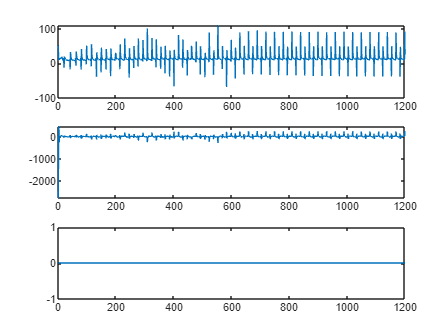


if(noZ)
    W_est = [W_est zeros(length(W_est),1)];
end

W_est_full = kron(W_est, ones(blockSize,1));

figure
subplot(3,1,1), grid on
plot(W_est(:,1));
subplot(3,1,2), grid on
plot(W_est(:,2));
subplot(3,1,3), grid on
plot(W_est(:,3));

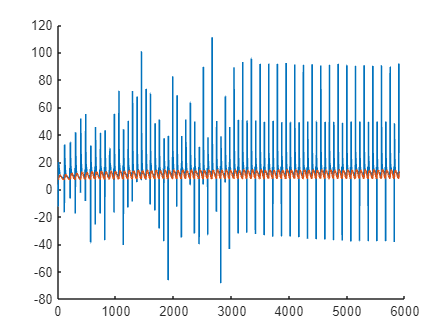


iFilterStart = 1+floor(N_filter/blockSize);
iSequence = iSequence(1,iFilterStart:end);
figure, hold on
plot(W_est_full(N_filter:end,1));
plot(W(N_filter:end,1))

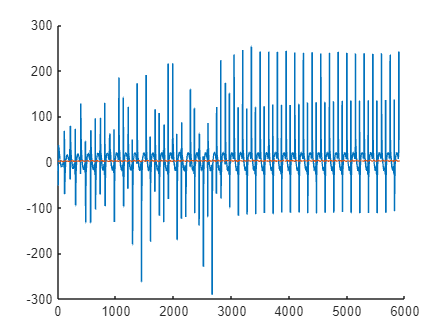


figure, hold on
plot(W_est_full(N_filter:end,2));
plot(W(N_filter:end,2))


% Factors for 
abs(norm(W_est(iFilterStart:end,1) - W(iSequence,1)))

ans = 594.1661

abs(norm(W_est_full(N_filter:5998,1)-W(N_filter:5998,1)))

ans = 1.3212e+03


meanX = mean(W_est_full(100:end,1))

meanX = 14.9636

meanY = mean(W_est_full(100:end,2))

meanY = 6.9280

meanZ = mean(W_est_full(100:end,3))

meanZ = 0

## Filtering Results

Starting with a threshold approach; the possibile problem with this approach is that it seems that spikes happen around the 'correct' value, so i.e. with a TH of 20, a spike from 12 to -9 will not be cancelled, but a spike from 12 to 21 will be cancelled

It's better to use the DataClearner app, that should more correctly remove outliers and smooth the data 

- For now we do it on W_est, but we could also do it on W_est_full

- Possibily we can do it also on alpha or beta, remove the spikes from the start

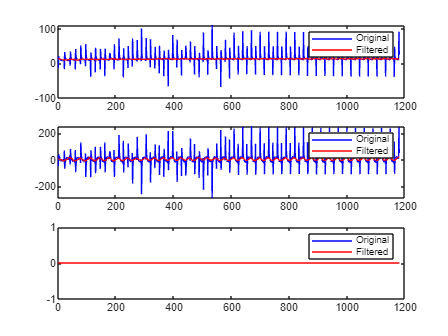

W_est_trunc = W_est(iFilterStart:end,:); % Skip first second 
W_est_table = array2table(W_est_trunc, 'VariableNames',{'Wx','Wy','Wz'});
W_est_table = filloutliers(W_est_table,"linear","movmedian",20,"DataVariables",["Wx","Wy"]);
W_est_table = smoothdata(W_est_table,"movmean",20,"DataVariables",["Wx","Wy"]);
W_est_fil = table2array(W_est_table);
figure;
subplot(3,1,1)
plot(W_est_trunc(:,1), 'b-'), hold on
plot(W_est_fil(:,1), 'r-');
legend('Original','Filtered'), hold off;
subplot(3,1,2)
plot(W_est_trunc(:,2), 'b-'), hold on
plot(W_est_fil(:,2), 'r-');
legend('Original','Filtered'), hold off;
subplot(3,1,3)
plot(W_est_trunc(:,3), 'b-'), hold on
plot(W_est_fil(:,3), 'r-');
legend('Original','Filtered'), hold off;

W_est_fil_full = kron(W_est_fil, ones(blockSize,1));


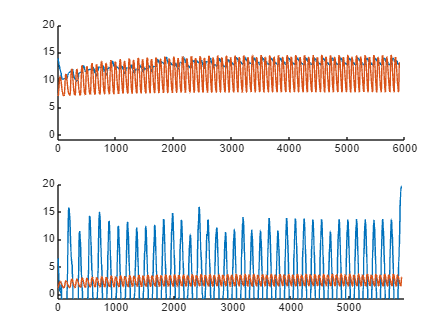

figure,
subplot(2,1,1),hold on
plot(W_est_fil_full(:,1));
plot(W(N_filter:end,1)),
ylim([-1;20]), hold off
subplot(2,1,2), hold on
plot(W_est_fil_full(:,2));
plot(W(N_filter:end,2)),
ylim([-1;20]), hold off

meanX = mean(W_est_fil_full(:,1))
meanY = mean(W_est_fil_full(:,2))

meanZ = mean(W_est_fil_full(:,3))

meanX = 12.7215

meanY = 1.7121

meanZ = 0